# **LAB SESSION 03**

## **Probability of Independent Events.**

**Objective:** To find probability of independent events using MATLAB

**Introduction:**

    **Event:**

    An event is the proper subset of the sample space.

    For Example:

- **A**: The toss is Head        {H}

- **B**: The die gives Six        {6}

- **C**: The report is Positive {+ve)

    There are two types an Event;

- Independent Events

- Dependent Events

1.**    Independent Events:**

    Events that are not affected by previous events.

    For Example:

- In tossing a coin experiment

- In rolling a die experiment

2.**    Dependent Events:**

    Events that are affected by previous events.

    For Example:

- Disease likelihood

- Picking up random colored balls

** PROBABILITY LAW****:**

    The probability law assigns a non-negative number** P(A)** (called probability of **A**) to a set **A** of possible outcomes (called an Event), that encodes our belief about the '*collective likelihood'* of the elements of **A**.

    There are two types of Probability Law:

- Discrete Probability Law

- Discrete Uniform Probability Law

2.**    Discrete Uniform Probability Law:**

    If the Sample Space **S** consists of **n** possible outcomes which are equally likely i.e. have same probability to occur, then the probability of any Event **A **is given by

**P(A) = **$\frac{#\;\mathrm{of}\;\mathrm{Elements}\;\mathrm{in}\;\mathrm{Event}\;A}{#\;\mathrm{of}\;\mathrm{Elements}\;\mathrm{in}\;\mathrm{Sample}\;\mathrm{Space}\;S}$

Code for Independent Events

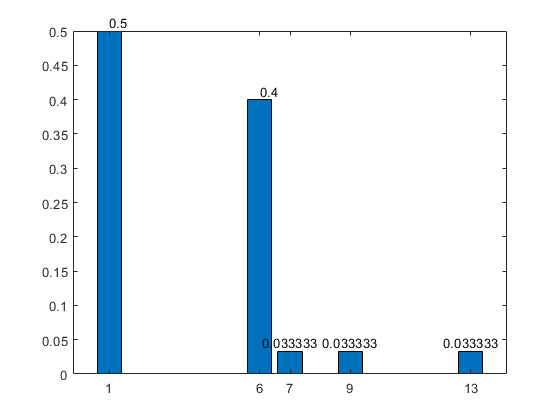

clear all
clc
S = [1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,6,6,6,6,6,6,6,6,6,6,6,6,7,9,13];
S = sort(S);

IP = input('Enter the Event:\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n<or> 3.SampleSpace (i.e: S) %for SampleSpace self%\n ');
IP = sort(IP);

i = 1;
ptr = 1;
Count = 1;

while (ptr <= length(IP))
    
    for j = (1+ptr):length(IP)
        
        if IP(ptr) == IP(j)
            Count = Count + 1;
        end
        
    end
    X(i) = IP(ptr);
    ptr = ptr + Count;
    Count = 1;
    i = i + 1;
end

for i = 1:length(X)
    Count = 0;
    for j = 1:length(S)
        if X(i) == S(j)
            Count = Count + 1;
        end
    end
    P(i) = Count/length(S);
end

bar(X,P)
text(X,P,num2str(P'),'HorizontalAlignment','center','Vertic','bottom')

*Some Important Definitions in this Code:*

- **S** = Sample Space Vector.

- **IP** = Input Event. It can be: [Scalar, Vector, Sample Space]

- **X** = Ordered Input Event with Repeativity removed

- **P **= Probability

For Scalar Input

Only one Scalar in an Event at a time is acceptable.

Results:

1. It runs for a single Scalar Events (e.g: 9)

2. It also runs for Scalar Events not in the sample space

For Vector Input

A collection of outcomes of Sample Space sholud be input in a Vector form.

Results:

1. Works for Non-Repeatitive ordered and disordered Input Vectors (e.g: [2] , [1,2,3] , [3,1,2,4])

2. Works for Repeatitive ordered and disordered Input Vectors (e.g: [2,2] , [1,1,2,3] , [1,2,2,3] , [2,1,1,3] , [1,1,2,3,4,4] , [2,4,4,5,9,9,9] , [1,6,6,3,2,2,3,4,1] )

For Sample Space Input

Enter S to Input Sample Space directly

Results:

1. Works for Non-Repeatitive ordered and disordered Sample Space Vector

2. Works for Repeatitive ordered and disordered Sample Space Vector          